**5. Suponha que o(s) motor(es) de um avião pode(m) falhar com probabilidade p e que as falhas são independentes entre motores. Suponha ainda que o avião se despenha se mais de metade dos motores falharem. Nestas condições, prefere voar num avião com 2 ou 4 motores? Utilize a distribuição que considerar mais adequada.**

**Sugestão: Tem pelo menos 2 alternativas: (1) obter expressões para a probabilidade de cada tipo de avião se despenhar em função de p e usar o quociente entre ambas para responder à questão, (2) efectuar os cálculos para um conjunto de valores concretos de p (ex: p= logspace(-3,log10(1/2),100)) e usar um gráfico mostrando simultaneamente as probabilidades de cada tipo de avião se despenhar.**

p = probabilidade de 1 motor falhar

Para o avião com dois motores cair, ambos os motores tem de falhar.

P(2 motores falharem) = C2,2*p^2*(1-p)^(2-2) = p^2

P(aviao cair) = p^2

Para o avião com quatro motores cair, 3 motores tem de falhar.

P(3 motores falharem) = C4,3*p^3*(1-p)^(4-3) = 4*p^3*(1-p) = 4p^3 - 4p^4

P(4 motores falharem) = C4,4*p^4*(1-p)^(4-4) = p^4

P(aviao cair) =  4p^3 - 4p^4 + p^4 = 4p^3 - 3p^4

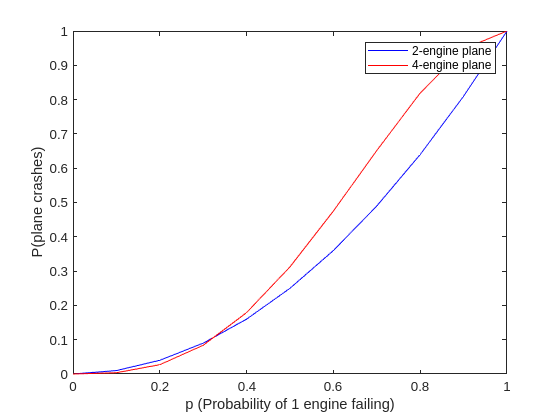

x = 0:0.1:1;
p2 = x.^2;
p4 = 4.*x.^(3)-3.*x.^(4);

figure;
plot(x, p2, 'b', 'DisplayName', '2-engine plane');
hold on;
plot(x, p4, 'r', 'DisplayName', '4-engine plane');
xlabel('p (Probability of 1 engine failing)');
ylabel('P(plane crashes)');
legend;
hold off;

Conclusão:

Se a probabilidade for menor que aproximadamente 0.3, é mais seguro o aviao com quatro motores.

Acima disso...

N = 1e5;

p = logspace(-3, log10(1), 100); % 0 a 1
aviao2 = zeros(1,100);
aviao4 = zeros(1,100);

for i = 1 : length(p)
    aviao2(i)= sum(sum(rand(2, N) < p(i)) >= 1)/N;
    aviao4(i)= sum(sum(rand(4, N) < p(i)) >= 2)/N;
end

crash2 = sum(aviao2)/100;
crash4 = sum(aviao4)/100;

fprintf("crash do aviao de 2 motores-> %f\n",crash2);

crash do aviao de 2 motores-> 0.219759


fprintf("crash do aviao de 4 motores-> %f\n",crash4);

crash do aviao de 4 motores-> 0.160337
